# **Propagation of Gaussian wave**

**a Gaussian beam has gaussian distribution**

## **Input beam:**

First, we plot the intensity figure of the  beam using the  following code:

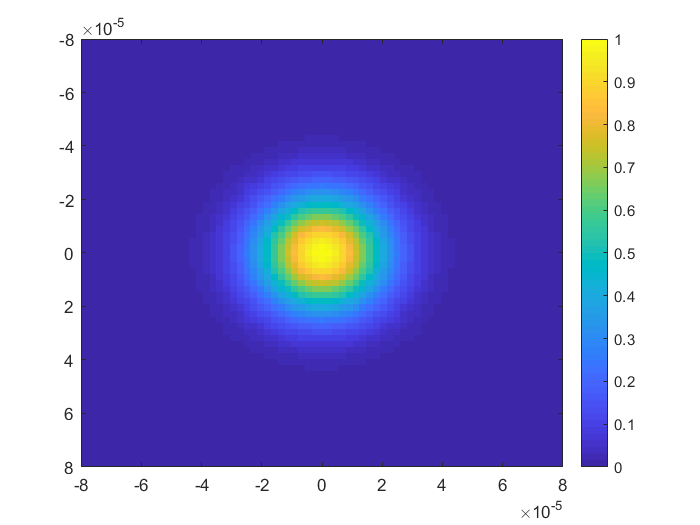

lm = 3.2 * 10^-6;
w0 = 30 * 10^-6;
k  = 2*pi/lm;
dx = sqrt(2)*pi/k;
dy = sqrt(2)*pi/k;
dk = 2*pi/dx;
num_samples = 1001;
x = linspace(-((num_samples-1)/2)*dx,((num_samples-1)/2)*dx,num_samples);
y = linspace(-((num_samples-1)/2)*dy,((num_samples-1)/2)*dy,num_samples);
z0 = (pi*w0^2)/lm;
[X,Y] = meshgrid(x,y);
u = exp(-(X.^2+Y.^2)/w0^2);
I = u.^2;
imagesc(x,y,I)
colorbar;
xlim([-8e-5 8e-5]);
ylim([-8e-5 8e-5]);

you can see the 3D bell curve shapw in the image and in the graph with x-axis below as expected.

second we  find the  corresponding index of the vector  y where the value  of the y-axis is equal to 0 and plot the corresponding intesity with the x-axis.

**notice:** to get the electromagnetic beam intensity we square the distribution equation.

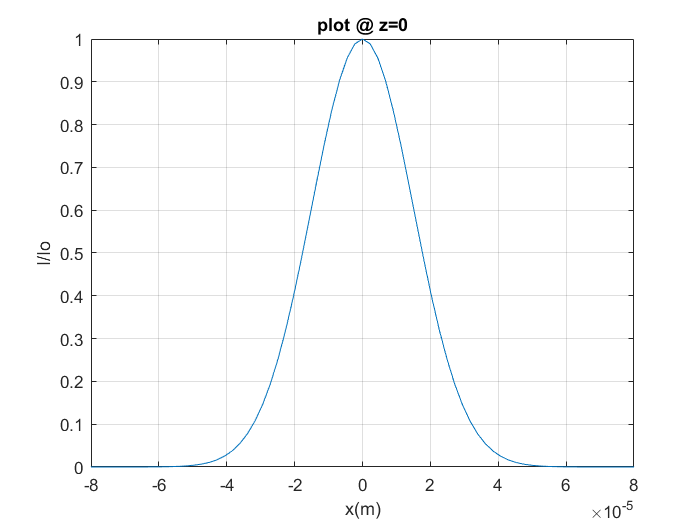

a = find(y==0);
ix = I(:,a);
plot(x,ix);
xlim([-8e-5 8e-5]);
grid on;
xlabel('x(m)');
ylabel('I/Io');
title('plot @ z=0');

Now we get the kx ,ky and kz:

z = 0.5;
U = fftshift(fft2(u));
kx = linspace(-dk/2,dk/2,num_samples);
ky =linspace(-dk/2,dk/2,num_samples);
[Kx,Ky] = meshgrid(kx,ky);
kz = k - (Kx.^2 + Ky.^2)/(2*k);

now to get the value of the intensity after propagating a distance z*zo we calulate the fourier  transform of the distirbution and shift its phase by a value of kz*z*zo and multiply the waist wo by a factor  equal to 1/sqrt(1+z^2).

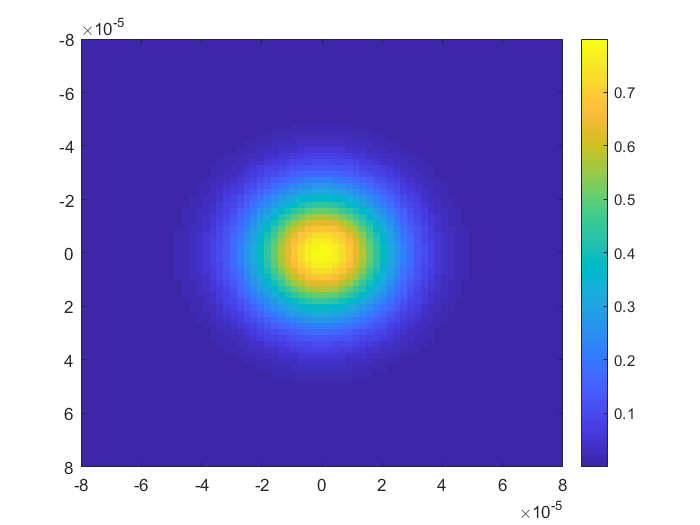

Uz0 = U .* exp(-1i*z*z0 .* kz);
uz0 =  ifft2(Uz0);
iz0  = abs(uz0).^2;
imagesc(x,y,iz0);
colorbar;
xlim([-8e-5 8e-5]);
ylim([-8e-5 8e-5]);

as we increase the z value ,the variation in the curve increases and its maximum decreases.

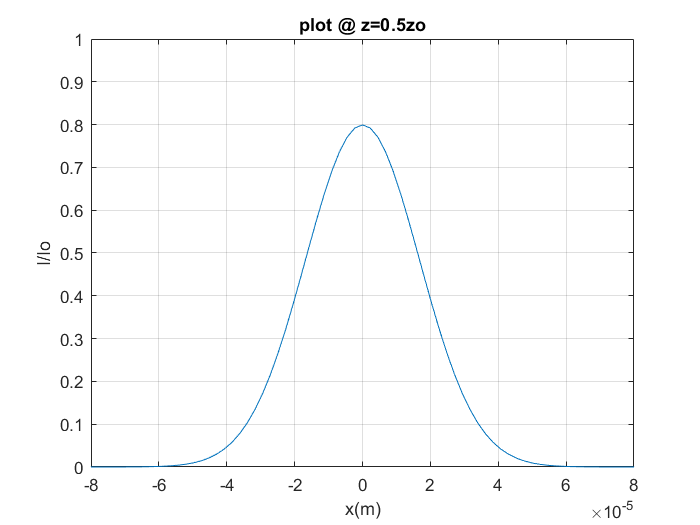

ix0 = iz0(:,a);
plot(x,ix0);
    xlim([-8e-5 8e-5]);
    ylim([0 1]);
    ylabel('I/Io');
    xlabel('x(m)');
    title('plot @ z=0.5zo');
    grid  on;

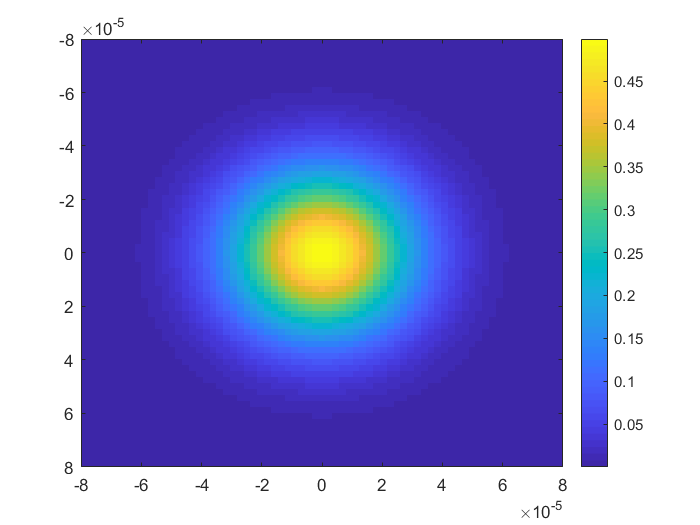

z = 1;
U = fftshift(fft2(u));
Uz1 = U .* exp(-1i*z*z0 .* kz);
uz1 =  ifft2(Uz1);
iz1  = abs(uz1).^2;
imagesc(x,y,iz1);
colorbar;
xlim([-8e-5 8e-5]);
ylim([-8e-5 8e-5]);

Now we  do the same process  for z =1 & z = 2 and we expect  the intesity of the beam to decrease and spread out over x-y plane (and x-axis @y=0).

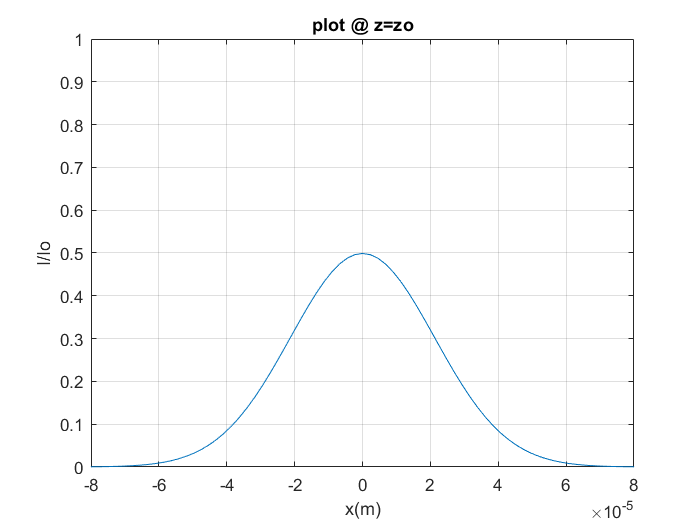

ix1 = iz1(:,a);
plot(x,ix1);
xlim([-8e-5 8e-5]);
ylim([0 1]);
ylabel('I/Io');
xlabel('x(m)');
grid  on;
title('plot @ z=zo');

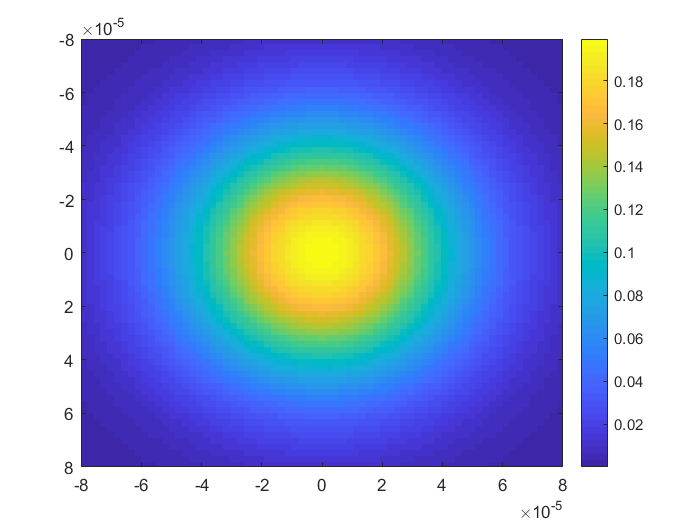

z = 2;
U = fftshift(fft2(u));
Uz2 = U .* exp(-1i*z*z0 .* kz);
uz2 =  ifft2(Uz2);
iz2  = abs(uz2).^2;
imagesc(x,y,iz2);
colorbar;
xlim([-8e-5 8e-5]);
ylim([-8e-5 8e-5]);

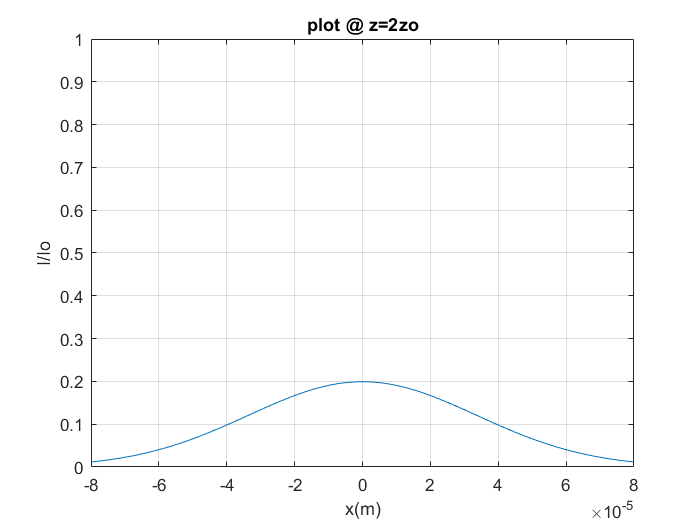

ix2 = iz2(:,a);
plot(x,ix2);
xlim([-8e-5 8e-5]);
ylim([0 1]);
ylabel('I/Io');
xlabel('x(m)');
grid  on;
title('plot @ z=2zo');